clear
load 'calibration data'\wheel_velocities_trial_1.mat
wheel_data = data;

left_wheel = wheel_data(:,1);
right_wheel = wheel_data(:,2);
left_wheel ./ right_wheel

ans =        NaN
       NaN
    1.1667
    1.1667
    1.0741
    1.0741
    1.2000
    1.2000
    1.2500
    1.2703


time = 0:0.005:0.005*(length(right_wheel)-1);

plot(time, left_wheel); hold on
plot(time, right_wheel); hold off
legend("Right Wheel", "Left Wheel", Location="southeast")

syms s t K tau 
M(s) = (K/tau)/(s+1/tau)

$$M(s) = \frac{K}{\tau \,\left(s+\frac{1}{\tau }\right)}$$

step(s) = 200/s

$$step(s) = \frac{200}{s}$$

m(t) = ilaplace(M(s)*step(s))

$$m(t) = 200\,K-200\,K\,{\mathrm{e}}^{-\frac{t}{\tau }}$$

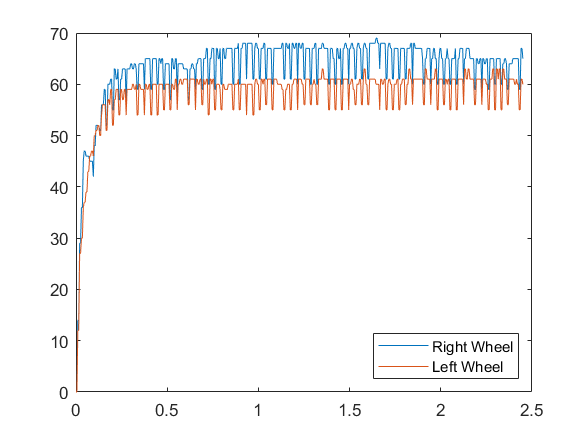

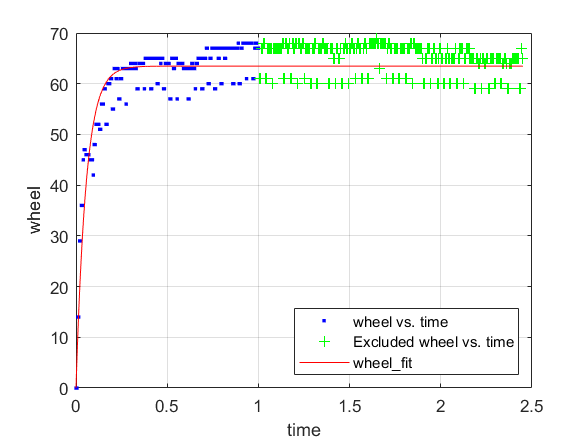


[left_fitresult, left_gof] = wheel_fit(time, left_wheel);

left_k = left_fitresult.k

left_k = 0.3174

left_tau = left_fitresult.tau

left_tau = 0.0554

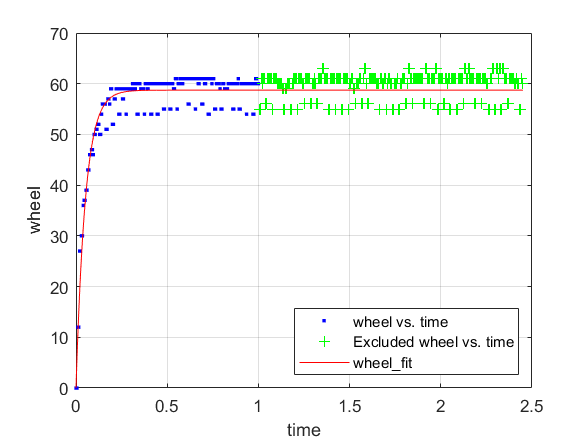


[right_fitresult, right_gof] = wheel_fit(time, right_wheel);

right_k = right_fitresult.k

right_k = 0.2936

right_tau = right_fitresult.tau

right_tau = 0.0515